clear all
close all
clc
set(gcf,'Visible','on')
syms m p w0

% f = logspace(0,6,1000);
% 
% H = 1./(1+2*m*(p/w0)+(p.^2/w0^2));

m = 0.2;
w0 = 2*pi*1e3;
% p = 1i*2*pi.*f;


% % Bode
% H = subs(H);
% G = 20.*log10(abs(H));
% subplot(2,1,1)
% semilogx(f,G);
% title("Diagramme de Bode")
% 
% subplot(2,1,2)
% semilogx(f,angle(H));
% title("Argument")

% Dirac
syms p t

fs = 100

fs = 100

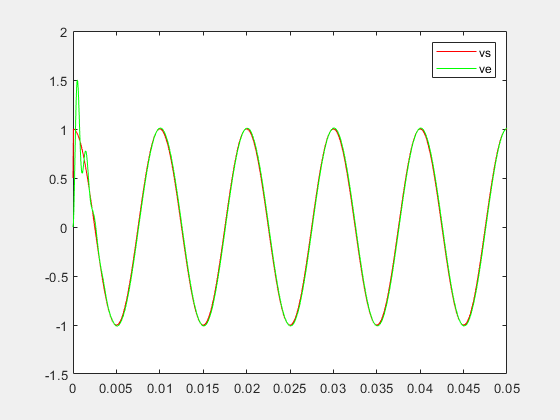


A = dirac(t);
B = heaviside(t);
C = cos(2*pi*fs.*t).*B;

ve = C;

% H = tl(vs)/tl(ve)
TLve = laplace(ve,t,p); % Laplace
H1 = 1/(1+2*m*(p/w0)+(p/w0)^2);
vs = ilaplace(H1*TLve,p,t);

t = linspace(0,5e-2,1000);
ve = subs(ve);
vs = subs(vs);

plot(t, ve,'r')
hold on
plot(t,vs,'g')
legend("vs","ve");

% L'amplitude du signal d'entrée et du signal de sortie est la meme.


% Fréquence de résonnance = fréquence du signal étudié
% La fréquence de résonnance indique le déplasage lorsqu'elle croise la 
% courbe des angles.
% Le déphasage mesuré par le diagramme de Bode se retrouve dans le tracé
% de vs ve.

[max_ve,Ive] = max(ve)

$$max\_ve = 1$$

Ive = 1000

[max_vs,Ivs] = max(vs(100:1:end));
G = double(20*log10(max_vs/max_ve));

delta = t(Ivs)-t(Ive);
% Delta est le décalage temporel.

display(G);

G = 0.0802

display(delta);

delta = -0.0449

dephasage = mod(delta*360*fs,360);
% Produit en croix entre 
% décalage temporel -> fréquence
% déphasage -> 360